# Calcium source extraction Demo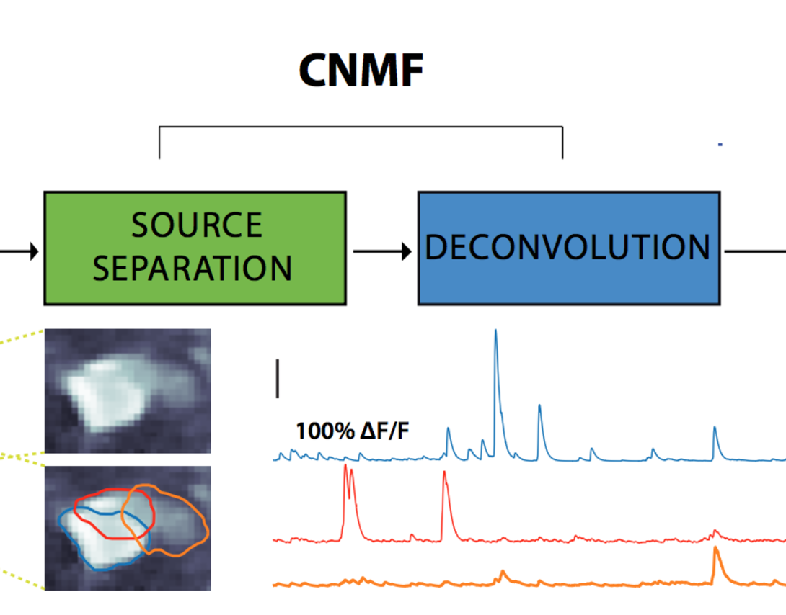

From E. Pnevmatikakis 

Free software; you can redistribute it and/or modify it under the terms of the GNU General Public License. [http://www.gnu.org/licenses/](http://www.gnu.org/licenses/)

Look at the [License](https://github.com/epnev/ca_source_extraction/license.txt) For more detail and the [ReadMe](https://github.com/epnev/ca_source_extraction/) for more information about this code.

clear;
addpath(genpath('utilities'));

# Load the file 

learn more about this process and the parameters here : [Documentation](https://github.com/epnev/ca_source_extraction/documentation.pdf)   

nam = 'demoMovie.tif';          % insert path to tiff stack here
sframe=1;			% user input: first frame to read (optional, default 1)
num2read=2000;	% user input: how many frames to read   (optional, default until the end)
Y = bigread2(nam,sframe,num2read);

Reading from frame 1 to frame 2000 of 2000 total frames


Finished reading images



if ~isa(Y,'double');    Y = double(Y);  end  % convert to single
[d1,d2,T] = size(Y);                                % dimensions of dataset
d = d1*d2;                                          % total number of pixels
play_movie({Y},{''},0,1000);


# Set parameters

K = 40;                                % number of components to be found
tau = 4;                               % std of gaussian kernel (size of neuron) 
p = 2 % order of autoregressive system 

p = 2

 %(p = 0 no dynamics, p=1 just decay, p = 2, both rise and decay)
merge_thr = 0.8;                                  % merging threshold

options = CNMFSetParms(...                      
    'd1',d1,'d2',d2,...               % dimensions of dataset                                  
    'search_method','dilate','dist',3,...    % search locations when upd. spatial comp.
    'deconv_method','constrained_foopsi',...    % activity deconvolution method
    'temporal_iter',2,...                       % number of block-coordinate descent steps 
    'fudge_factor',0.98,...                     % bias correction for AR coefficients
    'merge_thr',merge_thr,...                    % merging threshold
    'gSig',tau...
    );

# Preprocessing of the datas and initialization of the components 

- here, we compute the mean of the noise spectral density

- then, we initialize each component with a greedy algorithm for the ROI (components that have been spatially filtered using a gaussian kernel )

- we then operate a rank1 NMF on those components using the HALS algorithm

see More : NMF AND ROI :[http://www.cell.com/neuron/fulltext/S0896-6273(15)01084](http://www.cell.com/neuron/fulltext/S0896-6273(15)01084-3)

Simultaneous Denoising, Deconvolution, and Demixing of Calcium Imaging Data by [Eftychios A. Pnevmatikakis](javascript:void(0);) & al. 

    [P,Y] = preprocess_data(Y,p); 

Estimating the noise power for each pixel from a simple PSD estimate...  done 


# Fast initialization of spatial components using greedyROI and HALS

## HALS

##  
$$min_{f_j,g_j} J_j = || X^{(j)}  - f_jg_j^T||^2_F$$


## 
$$f_j \leftarrow {1 \over{g_j^Tg_j} }*[X^Jg_j]$$


## 
$$g_j \leftarrow {1 \over{f_j^Tf_j} }*[X^Jf_j]$$


HALS : (Keigo Kimura et al.) [http://proceedings.mlr.press/v39/kimura14.pdf](http://proceedings.mlr.press/v39/kimura14.pdf)

 [Ain,Cin,bin,fin,center] = initialize_components(Y,K,tau,options,P);  % initialize

No spatial downsampling is performed. Consider spatial downsampling if the field of view is very large. 
No temporal downsampling is performed. Consider temporal downsampling if the recording is very long. 
starting resampling 
Initializing components with greedy method 
found 10 out of 40 neurons..
found 20 out of 40 neurons..
found 30 out of 40 neurons..
found 40 out of 40 neurons..
Refining initial estimates with HALS...Starting parallel pool (parpool) using the 'local' profile ... 

connected to 2 workers.
  done 


# Display centers of found components

Found by convolving a gaussian kernel to each pixel of the image 

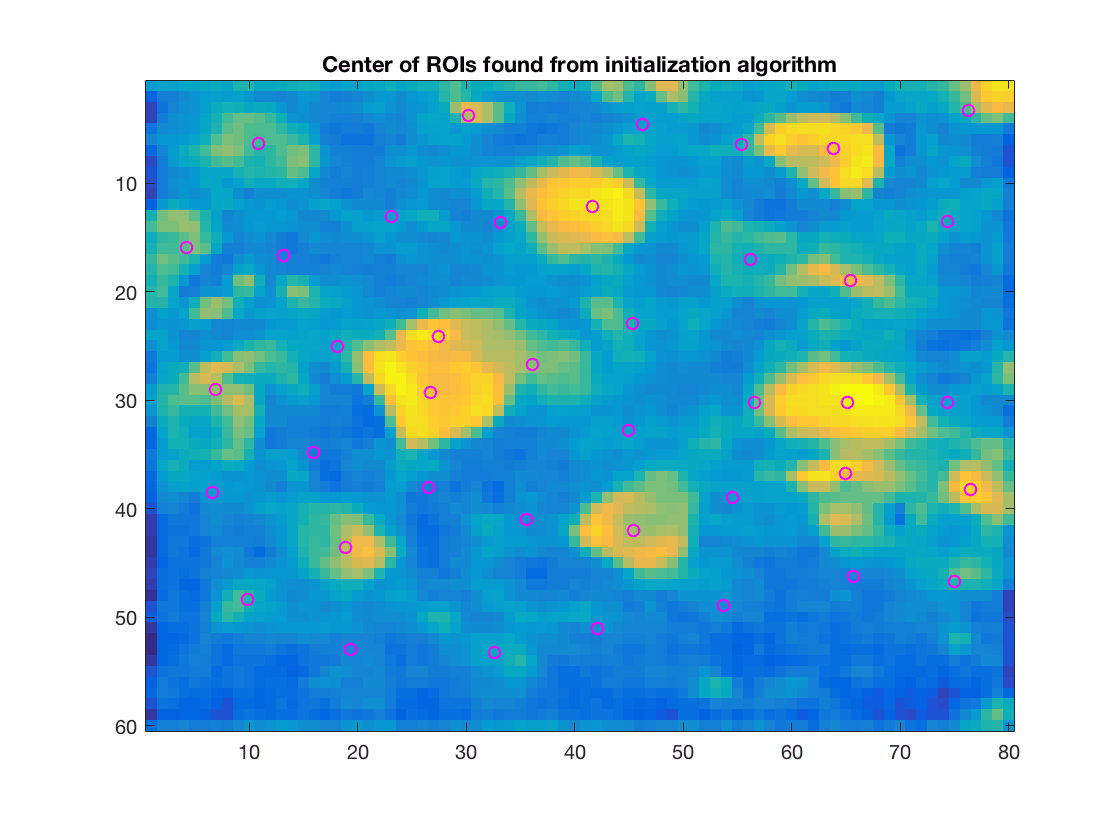

Cn =  correlation_image(Y); %reshape(P.sn,d1,d2);max(Y,[],3);td(Y,[],3);
 %image statistic (only for display purposes)
figure;imagesc(Cn);
    axis equal; axis tight; hold all;
    scatter(center(:,2),center(:,1),'mo');
    title('Center of ROIs found from initialization algorithm');

    drawnow;

# Manually refine components 

Set this to true to see what happens..

[Ain,Cin,center] = manually_refine_components(Y,Ain,Cin,center,Cn,tau,options);

# CNMF process (on patches)

*We are considering the video as a matrix called Y of dimension height x widht x frames*

`we now want to find A, C and B such that Y = A x C + B.`

`B being the Background, composed of its spatial b and temporal f component A being the spatial component of the neurons (also seen as their shape) C being the temporal component of the neurons (also seen as their calcium activity or traces)`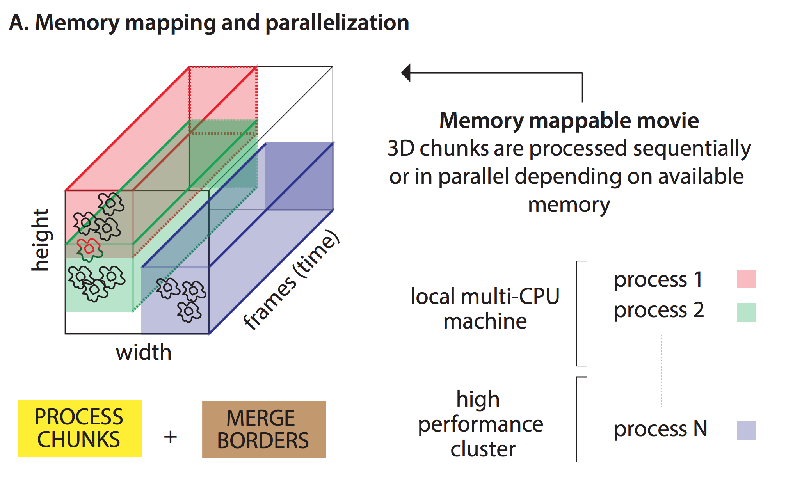

# Update spatial 

will consider C as fixed and try to update A.

`the process will be the following :  `

## intialization of each parameters

## testing of the input values

## finding relevant pixels

 in that should belong to the neuron using either an iterative structure or an ellipse to look around the center of mass of the neuron ( cm found in the initialization )

- this will be define a first shape of the neuron

- /!\ pixels are usually unlinked

## computing the distance indicator

 a map of the distances of each relevant pixels to the center of mass of the neuron

## memory mapping the matrices C and Y 

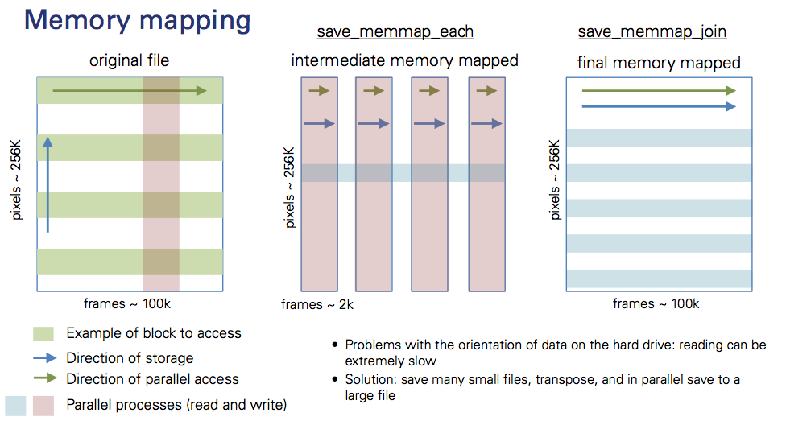

## updating the components in parallel :

- using ipyparralel

- solving this problem for each pixel of the component

## 
$$\arg \min_{A_i,B_i} \sum A_{i,:}
$$


##                                     s.t.

## 
$$||Y_i−A_iC+b_if||\leftarrow std_{noise}(i)×\sqrt T$$


- using the lasso lars method from scikit learn toolbox [https://en.wikipedia.org/wiki/Least-angle_regression](https://en.wikipedia.org/wiki/Least-angle_regression),[https://en.wikipedia.org/wiki/Lasso_(statistics](https://en.wikipedia.org/wiki/Lasso_(statistics)),[http://scikit-learn.org/stable/modules/linear_model.html#lars-lasso](http://scikit-learn.org/stable/modules/linear_model.html#lars-lasso)

## then, the newly refined components are thresholded (the C of the CNMF, one of the constrained here is that the matrix needs to be sparse) :

- first by applicating a median filtering [https://en.wikipedia.org/wiki/Median_filter](https://en.wikipedia.org/wiki/Median_filter)

- then by thresholding using a normalized user defined value

- continuing with a morphological closing of the components, using openCv functions [https://www.mathworks.com/help/images/ref/imclose.html](https://www.mathworks.com/help/images/ref/imclose.html) (the matlab version)

- we remove the unconnected pixels (we keep the large connected components )

## finnaly we compute the residuals (also called the background) which is computed as B=Y-AC

Yr = reshape(Y,d,T);
[A,b,Cin] = update_spatial_components(Yr,Cin,fin,[Ain,bin],P,options);

Updated spatial components 


# Update temporal 

will consider A as fixed and try to update C.

`the process will be the following :  `

## intialization of each parameters

## testing of the input values

## Generating residuals such that :

## 
$$Y_{resA} \leftarrow YA−(A^TAC)^T
$$


## Creating groups of components that can be processed in parallel

-  ones that are composed of not overlapping components

- using a simple greedy method

## Updating Calcium traces ( C ) multiple times

Using Oasis. which will deconvolve the spikes of each neurons from the Calcium traces matrix C. 

learn more : (Friedrich & al) [http://journals.plos.org/ploscompbiol/article?id=10.1371/journal.pcbi.1005423](http://journals.plos.org/ploscompbiol/article?id=10.1371/journal.pcbi.1005423)

See the demo here : [https://github.com/j-friedrich/OASIS/blob/master/examples/Demo.ipynb](https://github.com/j-friedrich/OASIS/blob/master/examples/Demo.ipynb)

          -  To infer the true shape of the calcium traces using an autoregressive framework

          -  To infer the most likely spike train ( also called particular events)

              It will find the probability of a spike train according to the mean and std of the C trace.

                       - - If it is superior to a threshold it is defined as a neural spike

                       - - This will give us a matrix which is itself constrained ( C from CNMF )

This is done in parallel using ipyparallel.

## We finally update the background

P.p = 0;    % set AR temporarily to zero for speed
[C,f,P,S,YrA] = update_temporal_components(Yr,A,b,Cin,fin,P,options);

14 out of 40 components updated 
25 out of 40 components updated 
35 out of 40 components updated 
40 out of 40 components updated 
14 out of 40 components updated 
25 out of 40 components updated 
35 out of 40 components updated 
40 out of 40 components updated 


# Classification of the components

  Perform several tests for component classification:

-     correlation test using the function classify_comp_corr

-     calculate the probability that max of each temporal component is due to noise through trace_fit_extreme.m

-    filter component based on min/max size

[ROIvars.rval_space,ROIvars.rval_time,ROIvars.max_pr,ROIvars.sizeA,keep] = classify_components(Y,A,C,b,f,YrA,options);

# run GUI for modifying component selection

 (optional, close twice to save values)

Coor = plot_contours(A,Cn,options,1); close;
GUIout = ROI_GUI(A,options,Cn,Coor,keep,ROIvars);   
options = GUIout{2};
keep = GUIout{3};    

# Merging found components 

merge the components that overlaps and have a high temporal correlation

`the process will be the following :  `

## intialization of each parameters

## testing of the input values

## find a graph of overlapping components

- we look for connected ones

- we keep the one that are "connected enough" (above a threshold)

## On Each groups :

- We normalize the components to be able to compare them

- We sum them together

- we process a rank one NMF

- we compute the traces (deconvolution)

- We replace the neurons by the merged one

[Am,Cm,K_m,merged_ROIs,Pm,Sm] = merge_components(Yr,A(:,keep),b,C(keep,:),f,P,S,options);

## Look at the newly merged components

if ~isempty(merged_ROIs)
    i = 1; %randi(length(merged_ROIs));
    ln = length(merged_ROIs{i});
    figure;
        set(gcf,'Position',[300,300,(ln+2)*300,300]);
        for j = 1:ln
            subplot(1,ln+2,j); imagesc(reshape(A(:,merged_ROIs{i}(j)),d1,d2)); 
                title(sprintf('Component %i',j),'fontsize',16,'fontweight','bold'); axis equal; axis tight;
        end
        subplot(1,ln+2,ln+1); imagesc(reshape(Am(:,K_m-length(merged_ROIs)+i),d1,d2));
                title('Merged Component','fontsize',16,'fontweight','bold');axis equal; axis tight; 
        subplot(1,ln+2,ln+2);
            plot(1:T,(diag(max(C(merged_ROIs{i},:),[],2))\C(merged_ROIs{i},:))'); 
            hold all; plot(1:T,Cm(K_m-length(merged_ROIs)+i,:)/max(Cm(K_m-length(merged_ROIs)+i,:)),'--k')
            title('Temporal Components','fontsize',16,'fontweight','bold')
        drawnow;
end

# Refine estimates

 excluding rejected components

Pm.p = p;    % restore AR value
[A2,b2,C2] = update_spatial_components(Yr,Cm,f,[Am,b],Pm,options);

Updated spatial components 


[C2,f2,P2,S2,YrA2] = update_temporal_components(Yr,A2,b2,C2,f,Pm,options);

13 out of 30 components updated 
22 out of 30 components updated 
28 out of 30 components updated 
30 out of 30 components updated 
13 out of 30 components updated 
22 out of 30 components updated 
28 out of 30 components updated 
30 out of 30 components updated 


# Order components

ordering of the found components based on their maximum temporal activation and their size

[A_or,C_or,S_or,P_or] = order_ROIs(A2,C2,S2,P2); 
K_m = size(C_or,1);

# Extract DF/F values 

(optional)

## DF/F is  a ratio of the signal over the background. 

It is a way of normalizing the calcium traces signal against the high variability of its detected signal. Mainly due to modification in laser intensity, protein absorbtion ... 

Those modifications will create  different min and max values  as well as as a low temporal variation of the signal. 

It will allow us to make a right comparison of the signal over time and over different neurons.

More information [here](https://github.com/epnev/ca_source_extraction/docs/notes/DF_F_note.pdf) 

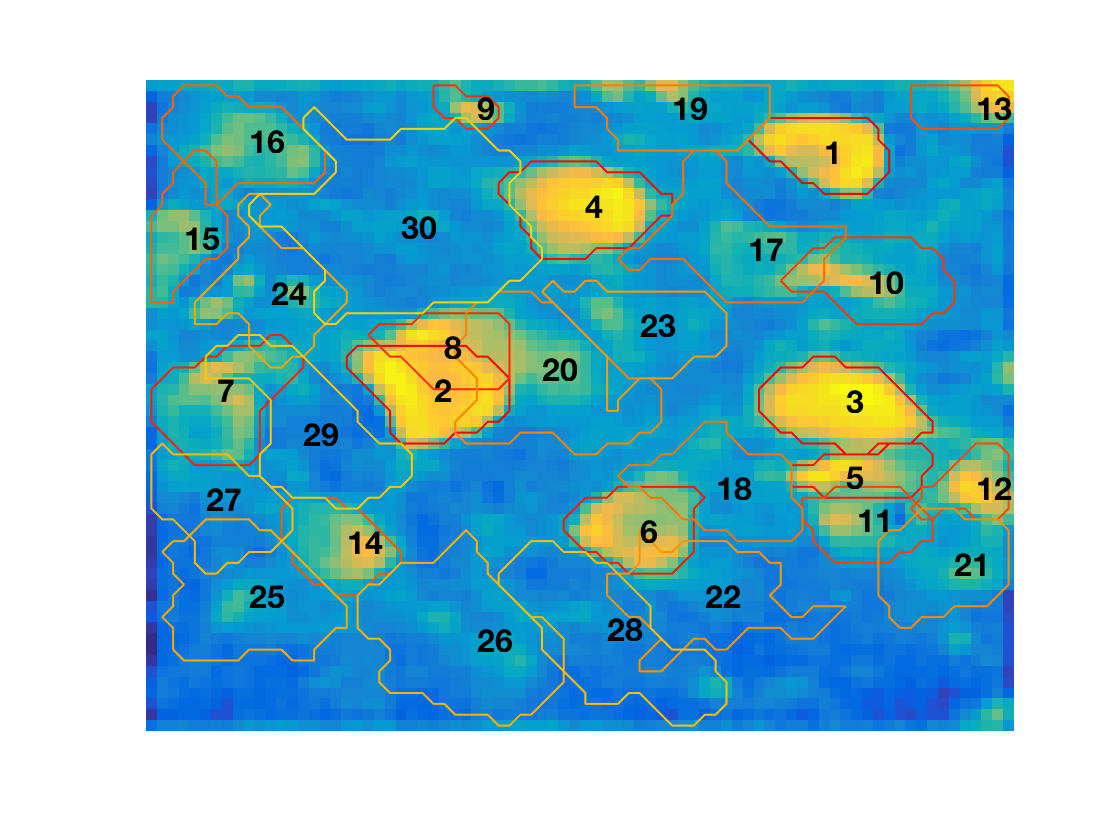

[C_df,~] = extract_DF_F(Yr,A_or,C_or,P_or,options); 
figure;
[Coor,json_file] = plot_contours(A_or,Cn,options,1); % contour plot of spatial footprints

# Save as a json file 

with component coordinates 

(Optional & requires matlab json library)

savejson('jmesh',json_file,'filename');  

Undefined function 'savejson' for input arguments of type 'struct'.


# Display the components

plot_components_GUI(Yr,A_or,C_or,b2,f2,Cn,options)

# Make the final movie

make_patch_video(A_or,C_or,b2,f2,Yr,Coor,options)